save_image = 0;

## Question 1

data = load("multicoil-data.mat");
im = data.im;
map1 = data.map1;
map2 = data.map2;

### Question 1.1

titles = {"Images %s from All Coils","Sensitivity %ss from All Coils (map 1)","Sensitivity %ss from All Coils (map 2)"};
to_be_plotted = {im,map1,map2};
for i = 1:3
    figure()
    figure('Units','pixels','Position',[100 100 1400 650]);

    t = tiledlayout(1,2 + (i == 1),'TileSpacing','compact','Padding','compact');
    
    nexttile
    montage(reshape(abs(to_be_plotted{i}),[224, 160, 1, 8]),'displayRange',[]);
    title(sprintf(titles{i},"Magnitude"))
    nexttile
    montage(reshape(angle(to_be_plotted{i}),[224, 160, 1, 8]),'displayRange',[]);
    title(sprintf(titles{i},"Phase"))
    if i == 1
        nexttile
        montage(reshape(log10(abs(fft2c(to_be_plotted{i}))+1),[224, 160, 1, 8]),'displayRange',[]);
        title("Magnitude Spectrums from All Coils")
    end

    if save_image
        exportgraphics(gcf,sprintf("q11_images_%i.png",i),'Resolution',300)
    end
end

### Question 1.2

C = reshape(map1,[224*160,8]);
m_l = reshape(im,[224*160,8]);
summation = sum(conj(C).*m_l,2);
normalisation = sum(abs(C).^2,2);
m_s = reshape(summation ./ normalisation,[224 160]);
m_s(isnan(m_s)) = 0;
m_ref = abs(m_s)/prctile(abs(m_s(:)),95); max_val = max(max(m_ref));
clf; imshow(m_ref,[0 max_val])
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.7, 0.7]);
title("OLC Recon (map1) - Reference Image")
if save_image
    exportgraphics(gcf,"q12_image.png",'Resolution',300)
end

### Question 1.3

C = reshape(map2,[224*160,8]);
m_l = reshape(im,[224*160,8]);
summation = sum(conj(C).*m_l,2);
normalisation = sum(abs(C).^2,2);
m_s = reshape(summation ./ normalisation,[224 160]);
m_s(isnan(m_s)) = 0;
m_s_normalised = abs(m_s)/prctile(abs(m_s(:)),95);
clf;
[PSNR1_3, SSIM1_3] = compare_images(m_s_normalised,m_ref,save_image,"q13_comp","OLC Recon (Map2)","Reference Image",max_val);

### Question 1.4

m_sos = reshape(sqrt(sum(abs(m_l).^2,2)),[224,160]);
m_sos_normalised = abs(m_sos)/prctile(abs(m_sos(:)),95);
m_ref2 = m_sos_normalised;
max_val2 = max(m_ref2(:));
[PSNR1_4, SSIM1_4] = compare_images(m_sos_normalised,m_ref,save_image,"q14_comp","Sum-of-Squares Recon","Reference Image",max_val);

{"Question","1.3","1.4";"PSNR",PSNR1_3,PSNR1_4;"SSIM",SSIM1_3,SSIM1_4}

## Question 2

### Question 2.1

Rxs = [1 1 2];
Rys = [2 4 2];
sizes = [2 1 2];

for i = 1:3
    Rx = Rxs(i);
    Ry = Rys(i);
    [imu, Mu] = undersample(im, Rx, Ry);
    figure()
    figure('Units','pixels','Position',[100 100 1400 650]);
    t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
    
    nexttile
    montage(reshape(abs(imu),[224/Rx, 160/Ry, 1, 8]),'displayRange',[],'Size',[sizes(i) 8/sizes(i)]);
    title(sprintf("Undersampled Coil Magnitude Images with Rx = %i, Ry = %i",Rx,Ry))
    nexttile
    montage(reshape(log10(abs(Mu)+1),[224/Rx, 160/Ry, 1, 8]),'displayRange',[],'Size',[sizes(i) 8/sizes(i)]);
    title(sprintf("Undersampled Coil Phase Images with Rx = %i, Ry = %i",Rx,Ry))
    if save_image
        exportgraphics(gcf,sprintf("q21_images_%i.png",i),'Resolution',300)
    end
end

### Question 2.2

im_sense = l2sense(im,map1,1,1,0);
[PSNR2_2, SSIM2_2] = compare_images(abs(im_sense),m_ref,save_image,"q22_comp","Sense Recon ($R_x,R_y,\lambda$) = 1,1,0","Reference Image",max_val)

### Question 2.3

PSNRs2_3 = zeros([3 1]);
SSIMs2_3 = zeros([3 1]);
for i = 1:3
    [imu_aliased, Mu_aliased] = undersample(im, Rxs(i), Rys(i));
    im_sense = l2sense(imu_aliased,map1,Rxs(i),Rys(i),0);
    [PSNRs2_3(i), SSIMs2_3(i)] = compare_images(abs(im_sense),m_ref,save_image,sprintf("q23_comp_%i_bad",i),sprintf("Sense Recon ($R_x,R_y,%s$) = %i,%i,0","\lambda",Rxs(i),Rys(i)),"Reference Image",max_val);
end

### Question 2.4

PSNRs2_4 = zeros([3 1]);
SSIMs2_4 = zeros([3 1]);
lambdas = [1.696 1.802 1.019]*0.01;
for i = 1:3
    [imu_aliased, Mu_aliased] = undersample(im, Rxs(i), Rys(i));
    im_sense = l2sense(imu_aliased,map1,Rxs(i),Rys(i),lambdas(i)+0.0001);
    [PSNRs2_4(i), SSIMs2_4(i)] = compare_images(abs(im_sense),m_ref,save_image,sprintf("q24_comp_%i",i),sprintf("Sense Recon ($R_x,R_y,%s$) = %i,%i,0","\lambda",Rxs(i),Rys(i)),"Reference Image",max_val);
end

### Question 2.5

PSNRs2_5 = zeros([3 1]);
SSIMs2_5 = zeros([3 1]);
lambdas = [1.696 1.802 1.019];
for i = 1:3
    [imu_aliased, Mu_aliased] = undersample(im, Rxs(i), Rys(i));
    im_sense = l2sense(imu_aliased,map2,Rxs(i),Rys(i),lambdas(i)+0.0001);
    [PSNRs2_5(i), SSIMs2_5(i)] = compare_images(abs(im_sense),m_ref,save_image,sprintf("q25_comp_%i",i),sprintf("Sense Recon ($R_x,R_y,%s$) = %i,%i,0","\lambda",Rxs(i),Rys(i)),"Reference Image",max_val);
end

### Question 2.6

No coding needed for this section.

### Question 2.7

for i = 1:3
    g_map = gfactor(map1,Rxs(i),Rys(i),lambdas(i));
    subplot(1,3,i)
    imshow(real(g_map),[0 5])
    title(sprintf("g-Factor Map $ R_x = %i,R_y = %i, %s = %.3f $",Rx,Ry,"\lambda",lambdas(i)),Interpreter="latex")
end
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.7, 0.7]);
if save_image
    exportgraphics(gcf,"q27_gmap.png",'Resolution',300)
end

### Question 2.8

for i = 1:3
    g_map = gfactor(map1,Rxs(i),Rys(i),lambdas(i) * 10^(-6));
    subplot(1,3,i)
    imshow(real(g_map),[0 5])
    title(sprintf("g-Factor Map $ R_x = %i,R_y = %i, %s = %.3f $",Rx,Ry,"\lambda",lambdas(i)),Interpreter="latex")
end
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.7, 0.7]);
if save_image
    exportgraphics(gcf,"q28_gmap.png",'Resolution',300)
end

r1 = {"Questions","2.2","2.3.1","2.3.2","2.3.3","2.4.1","2.4.2","2.4.3","2.5.1","2.5.2","2.5.3"};
r2 = [{"PSNRs"} num2cell([PSNR2_2, PSNRs2_3.', PSNRs2_4.', PSNRs2_5.'])];
r3 = [{"SSIMs"}, num2cell([SSIM2_2, SSIMs2_3.', SSIMs2_4.', SSIMs2_5.'])];
[r1;r2;r3]

## Question 3

### Question 3.1

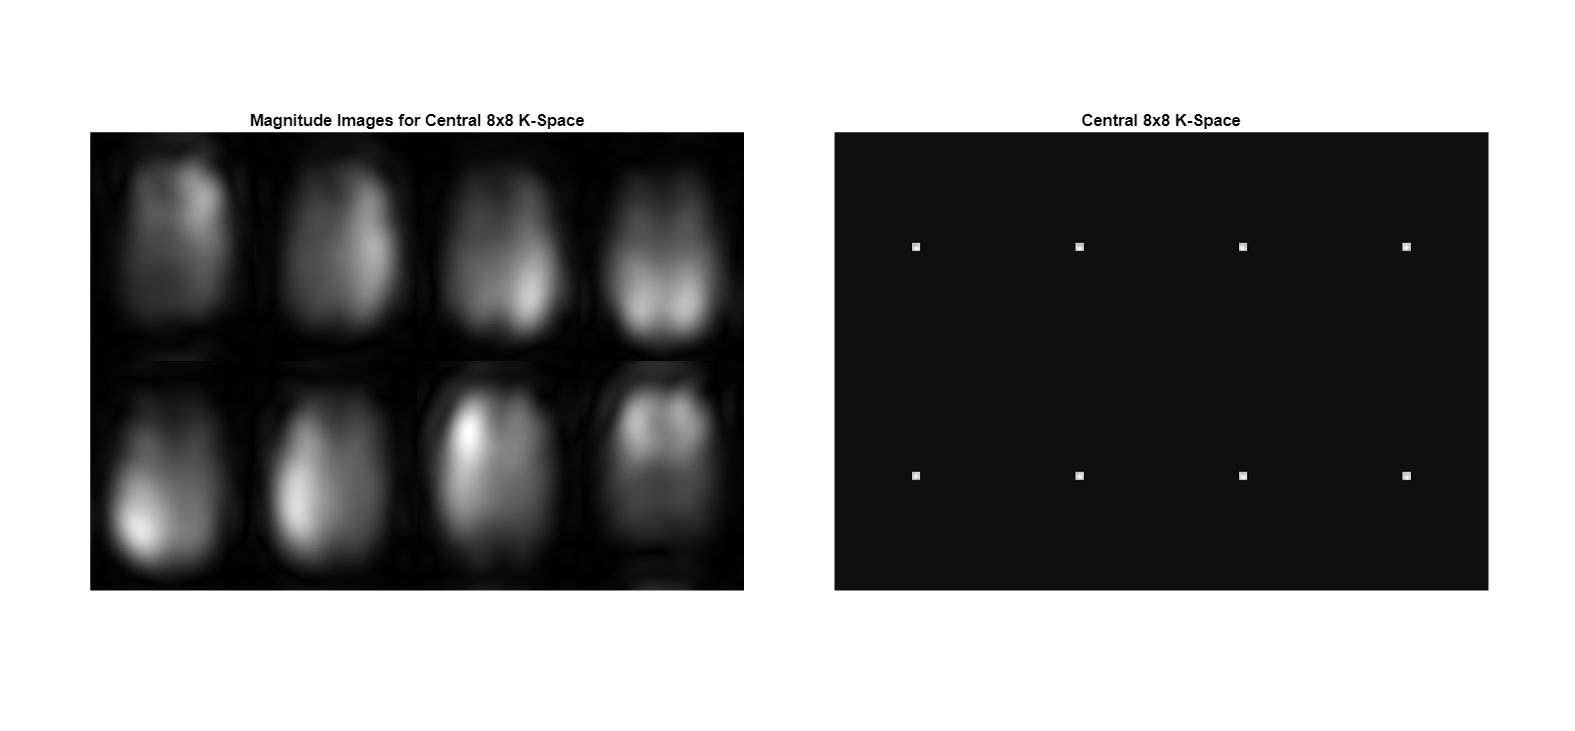

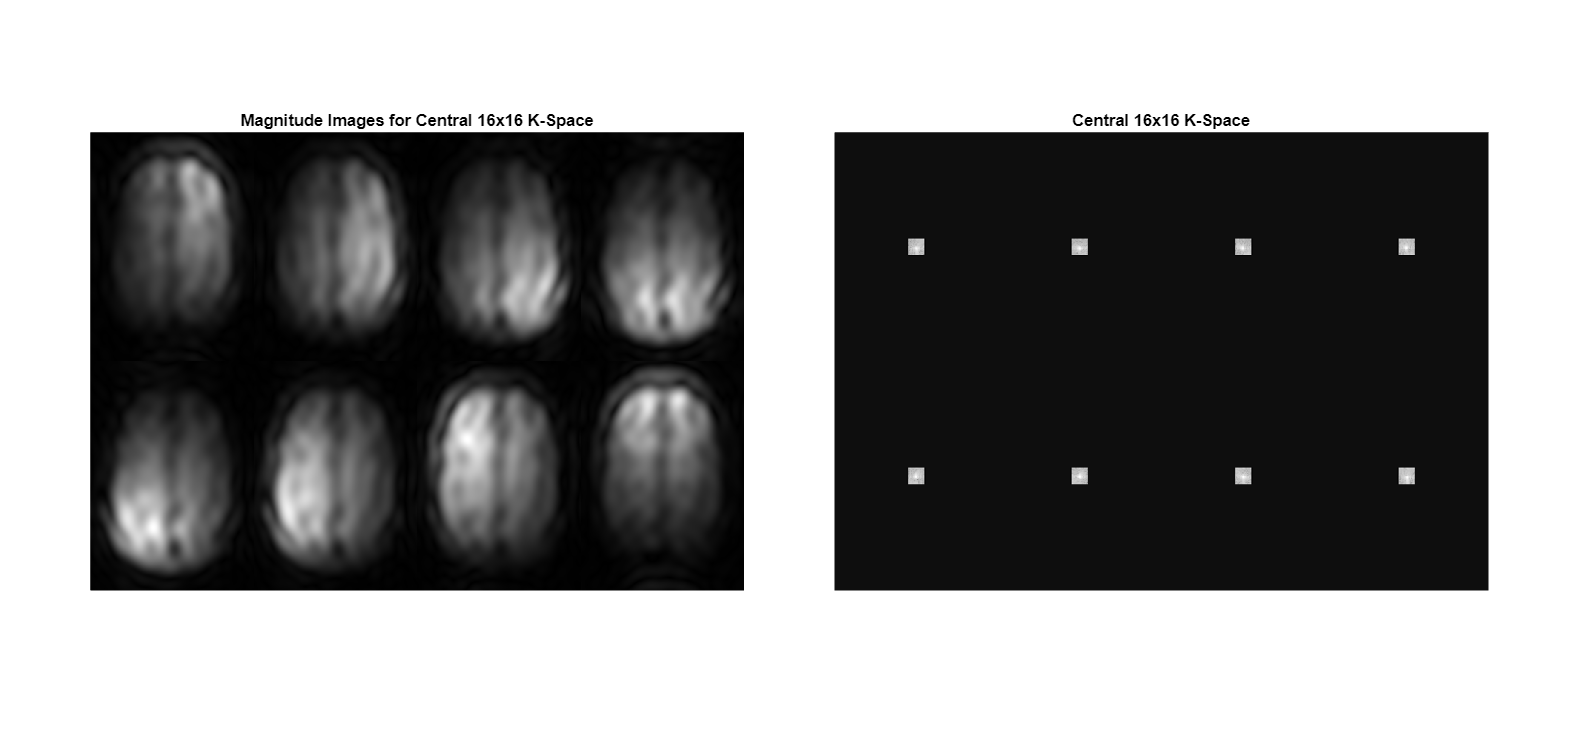

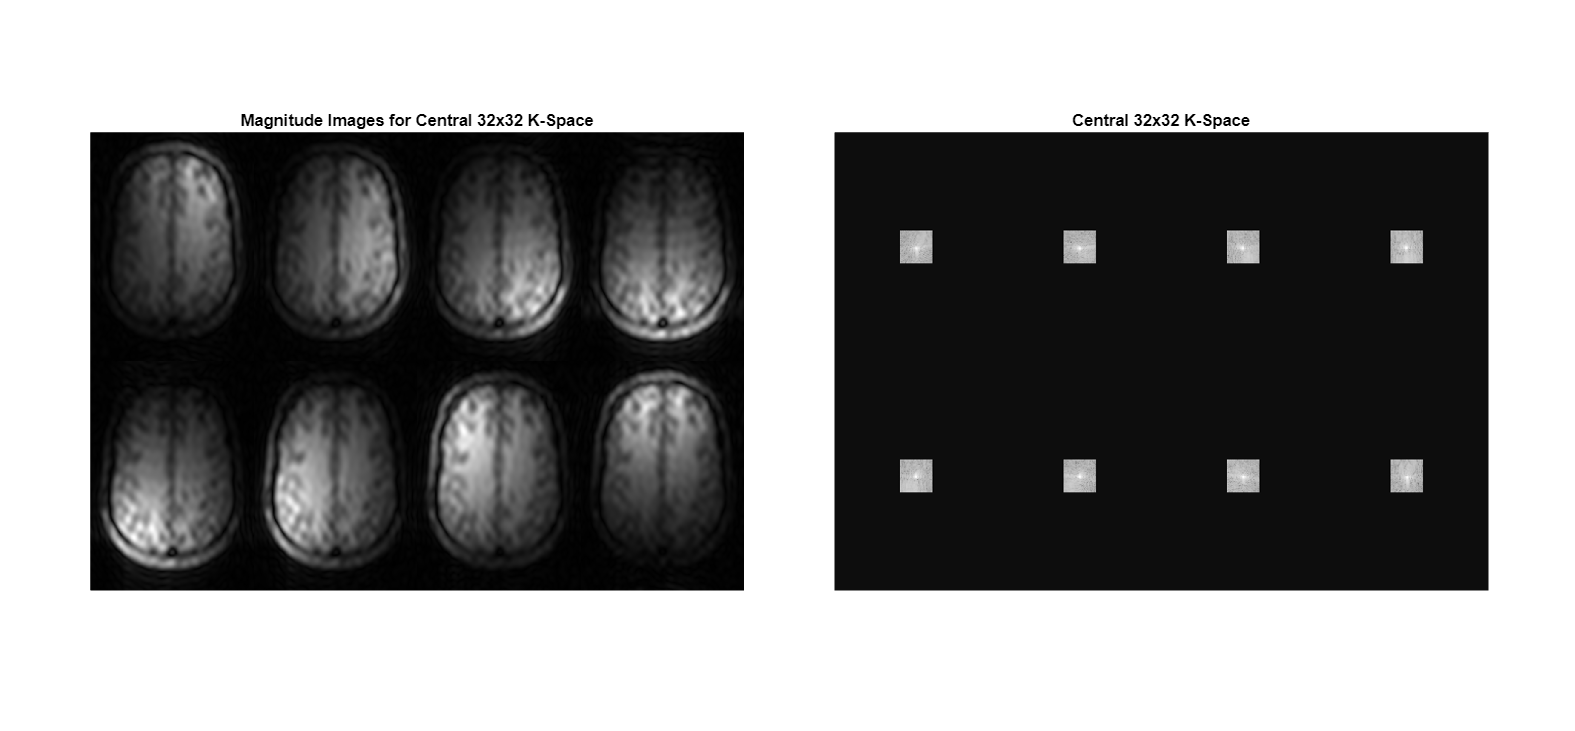

central_sizes = [8 16 32];
for i = 1:3
    [imc,Mc] = imcalib(im,central_sizes(i),central_sizes(i));
    figure()
    figure('Units','pixels','Position',[100 100 1400 650]);
    t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
    
    nexttile
    montage(abs(imc),'displayRange',[],'Size',[2 4]);
    title(sprintf("Magnitude Images for Central %ix%i K-Space",central_sizes(i),central_sizes(i)))

    nexttile
    montage(log10(abs(Mc)+1),'displayRange',[],'Size',[2 4]);
    title(sprintf("Central %ix%i K-Space",central_sizes(i),central_sizes(i)))
    if save_image
        exportgraphics(gcf,sprintf("q31_images_%i.png",i),'Resolution',300)
    end
end

### Question 3.2

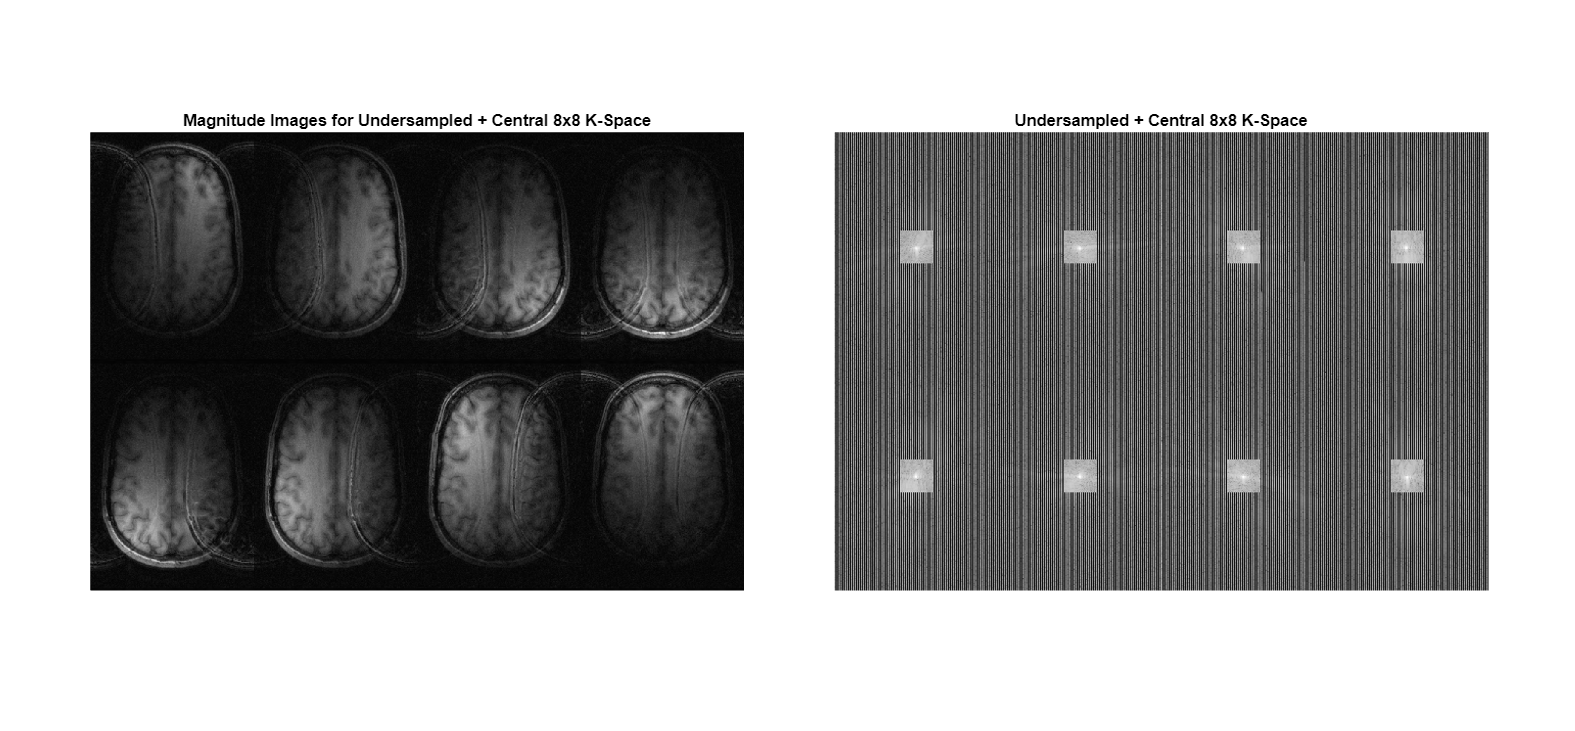

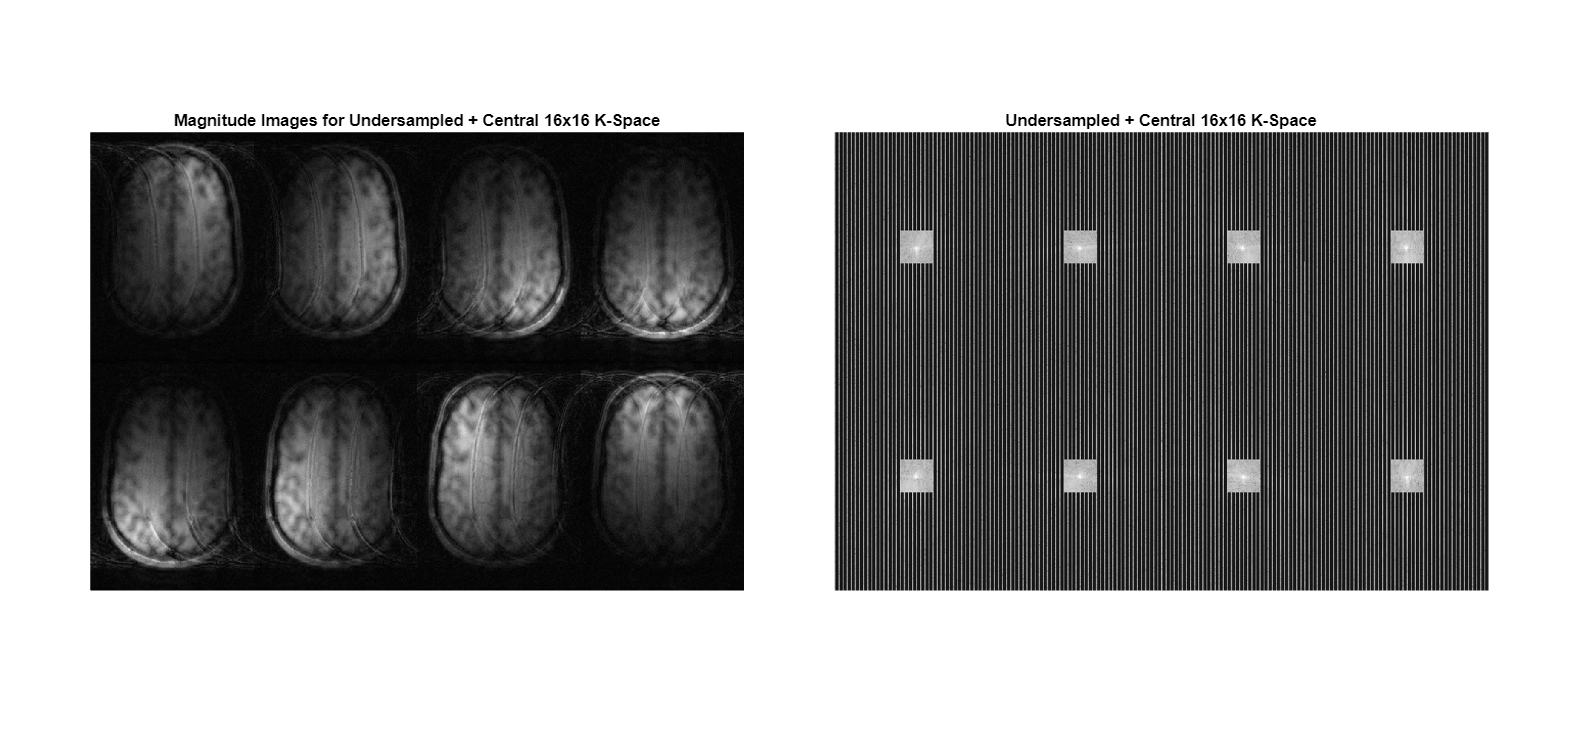

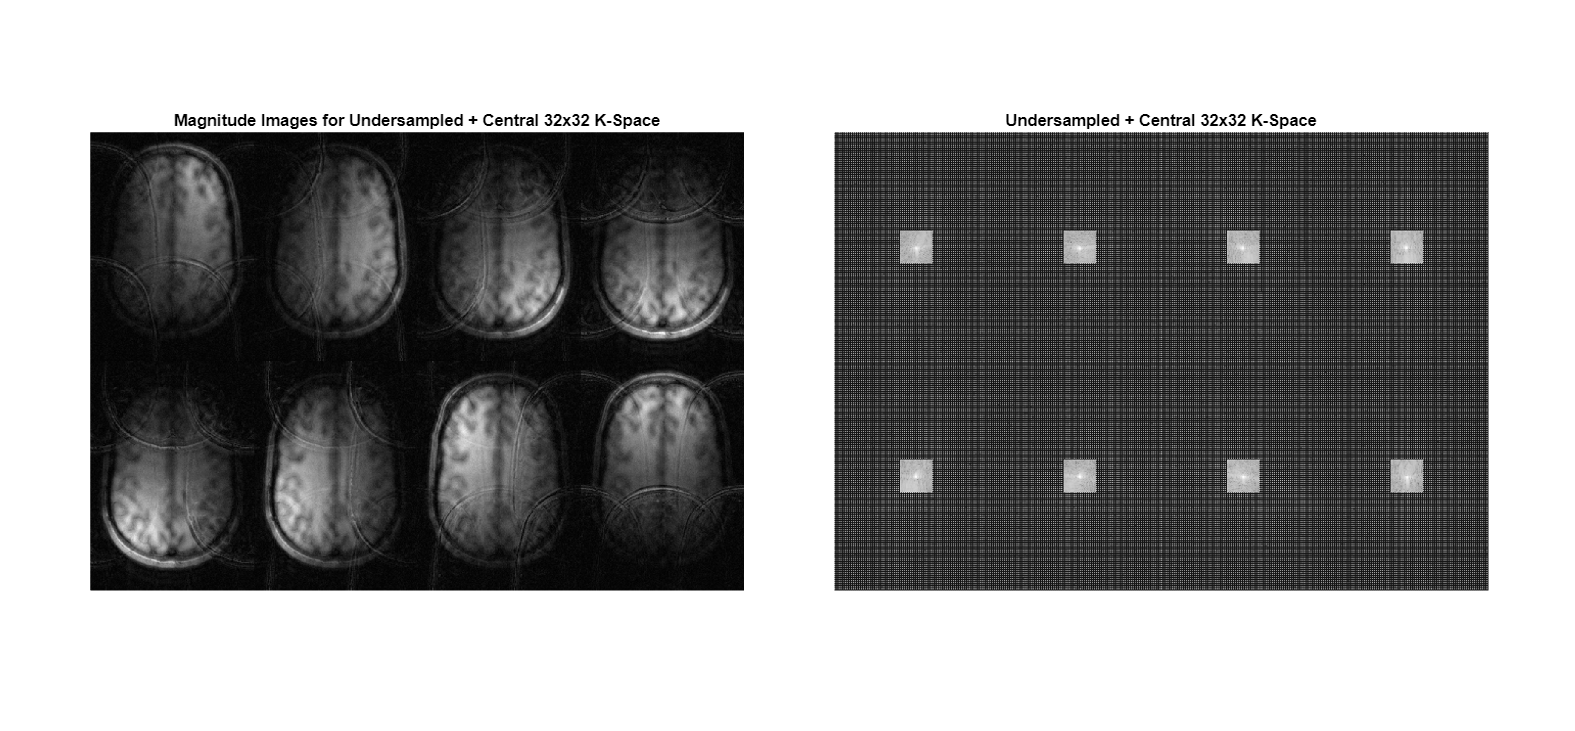

for i = 1:3
    [imu,Mu] = undersamplecalib(im,Rxs(i),Rys(i),32,32);
    figure()
    figure('Units','pixels','Position',[100 100 1400 650]);
    t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
    
    nexttile
    montage(abs(imu),'displayRange',[],'Size',[2 4]);
    title(sprintf("Magnitude Images for Undersampled + Central %ix%i K-Space",central_sizes(i),central_sizes(i)))

    nexttile
    montage(log10(abs(Mu)+1),'displayRange',[],'Size',[2 4]);
    title(sprintf("Undersampled + Central %ix%i K-Space",central_sizes(i),central_sizes(i)))
    if save_image
        exportgraphics(gcf,sprintf("q32_images_%i.png",i),'Resolution',300)
    end
end

### Question 3.3

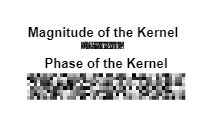

[imc,Mc] = imcalib(im,32,32);
lambda = 0;
kernel = calibrate(Mc,lambda);
clf;

imshow(abs(kernel.'),[])
title("Magnitude of the Kernel")
subplot(2,1,2)
imshow(angle(kernel.'),[])
title("Phase of the Kernel")
if save_image
    exportgraphics(gcf,"q33_kernel.png",'Resolution',300)
end

### Question 3.4

[imu,Mu] = undersamplecalib(im,1,2,32,32);
[imc,Mc] = imcalib(im,32,32);
lambda = 0;
[imr, Mr] = grappa(Mu, Mc, lambda);

figure()
figure('Units','pixels','Position',[100 100 1400 650]);
t = tiledlayout(1,2 + (i == 1),'TileSpacing','compact','Padding','compact');
nexttile
montage(reshape(abs(imr),[224, 160, 1, 8]),'displayRange',[]);
title("GRAPPA Reconstructed Magnitude Image for All Coils")
nexttile
montage(reshape(angle(imr),[224, 160, 1, 8]),'displayRange',[]);
title("GRAPPA Reconstructed Phase Image for All Coils")
if save_image
    exportgraphics(gcf,"q34_images.png",'Resolution',300)
end

m_sos3 = sqrt(sum(abs(imr).^2,3));
m_sos3_normalised = abs(m_sos3)/prctile(abs(m_sos3(:)),95);
[PSNR3_4, SSIM3_4] = compare_images(m_sos3_normalised,m_ref2,save_image,"q34_comp","GRAPPA Sum-of-Squares Recon","Reference Image - SoS",max_val2);

### Question 3.5

[imu,Mu] = undersamplecalib(im,1,2,32,32);
[imc,Mc] = imcalib(im,32,32);
lambda = 8.7879*10^10;

figure()
figure('Units','pixels','Position',[100 100 1400 650]);
t = tiledlayout(1,2 + (i == 1),'TileSpacing','compact','Padding','compact');
nexttile
montage(reshape(abs(imr),[224, 160, 1, 8]),'displayRange',[]);
title("Regularised GRAPPA Reconstructed Magnitude Image for All Coils")
nexttile
montage(reshape(angle(imr),[224, 160, 1, 8]),'displayRange',[]);
title("Regularised GRAPPA Reconstructed Phase Image for All Coils")
if save_image
    exportgraphics(gcf,"q35_images.png",'Resolution',300)
end

[imr, Mr] = grappa(Mu, Mc, lambda);
m_sos3 = sqrt(sum(abs(imr).^2,3));
m_sos3_normalised = abs(m_sos3)/prctile(abs(m_sos3(:)),95);
[PSNR3_5, SSIM3_5] = compare_images(m_sos3_normalised,m_ref2,save_image,"q35_comp","GRAPPA Sum-of-Squares Recon","Reference Image - SoS",max_val2);

### Question 3.6

No scripts required for this question

{"Questions","3.4","3.5";"PSNR",PSNR3_4,PSNR3_5;"SSIM",SSIM3_4,SSIM3_5}

## Functions

function [imr, Mr] = grappa(Mu, Mc, lambda)

    [Nx, Ny, Nc] = size(Mu);

    % Learn GRAPPA kernel from calibration data
    kernel = calibrate(Mc, lambda);   % size: (6*Nc) x Nc

    % Start from undersampled k-space
    Mr = Mu;

    % For Ry = 2, missing columns are the zero columns
    for x = 2:Nx-1
        for y = 2:Ny-1

            % Only fill missing k-space points
            if all(abs(Mr(x,y,:)) == 0)

                src = [];

                coords = [
                    x-1, y-1;
                    x,   y-1;
                    x+1, y-1;
                    x-1, y+1;
                    x,   y+1;
                    x+1, y+1
                ];

                valid = true;

                for k = 1:6
                    xx = coords(k,1);
                    yy = coords(k,2);

                    % Source points must be acquired / already available
                    if all(abs(Mr(xx,yy,:)) == 0)
                        valid = false;
                        break;
                    end

                    src = [src; squeeze(Mr(xx,yy,:))];
                end

                if valid
                    Mr(x,y,:) = src.' * kernel;
                end

            end
        end
    end

    % Inverse centered FFT to get reconstructed coil images
    imr = ifft2c(Mr);

end

function kernel = calibrate_T(Mc, lambda)
    [Nx, Ny, Nc] = size(Mc);

    % Find calibration region
    mask = abs(Mc(:,:,1)) > 0;
    [xs, ys] = find(mask);

    xmin = min(xs); xmax = max(xs);
    ymin = min(ys); ymax = max(ys);

    S = [];
    T = [];

    % Loop only inside calibration region
    % Avoid borders because we use x-1, x+1, y-1, y+1
    for x = xmin+1:xmax-1
        for y = ymin+1:ymax-1

            src = [];

            % 6 neighbors from 3x3 neighborhood
            coords = [
                x-1, y-1;
                x,   y-1;
                x+1, y-1;
                x-1, y+1;
                x,   y+1;
                x+1, y+1
            ];

            for k = 1:6
                xx = coords(k,1);
                yy = coords(k,2);

                % Add all coil values at this source location
                src = [src; squeeze(Mc(xx, yy, :))];
            end

            % Target: all coils at the missing location
            tgt = squeeze(Mc(x, y, :));

            S = [S; src.'];   % one equation/example
            T = [T; tgt.'];   % target values for all coils

        end
    end

    % Regularized least-squares solution
    kernel = (S' * S + lambda * eye(6*Nc)) \ (S' * T);
end

function kernel = calibrate(Mc, lambda)

[Nx, Ny, Nc] = size(Mc);

mask = sum(abs(Mc) > 0, 3);
[x_idx, y_idx] = find(mask);

x_min = min(x_idx);
x_max = max(x_idx);
y_min = min(y_idx);
y_max = max(y_idx);

S = [];
T = [];

for x = x_min+1 : x_max-1
    for y = y_min+1 : y_max-1

        source_block = Mc(x-1:x+1, [y-1 y+1], :);
        source_vec = reshape(source_block, [6*Nc, 1]);
        target_vec = reshape(Mc(x,y,:), [1, Nc]);

        S = [S; source_vec.'];
        T = [T; target_vec];
    end
end

kernel = (S' * S + lambda * eye(6*Nc)) \ (S' * T);

end

function [imu, Mu] = undersamplecalib(im, Rx, Ry, calibx, caliby)
    [imc,Mu] = imcalib(im,calibx,caliby);
    k = fft2c(im);
    Mu(1:Rx:end,1:Ry:end,:) = k(1:Rx:end,1:Ry:end,:);

    imu = ifft2c(Mu); 
end

function [imc, Mc] = imcalib(im, calibx, caliby)

    [Nx, Ny, Nc] = size(im);

    k_data = fft2c(im);

    Mc = zeros(size(k_data));

    cx = floor(Nx/2) + 1;
    cy = floor(Ny/2) + 1;

    x_range = cx - floor(calibx/2) : cx + floor(calibx/2) - 1;
    y_range = cy - floor(caliby/2) : cy + floor(caliby/2) - 1;

    Mc(x_range, y_range, :) = k_data(x_range, y_range, :);

    imc = ifft2c(Mc);
end

function g = gfactor(map,Rx,Ry,lambda)
    [Cx,Cy,Cz] = size(map);
    sx_aliased = Cx/Rx;
    sy_aliased = Cy/Ry; 
    sz_aliased = Cz;
    
    g = zeros(size(map(:,:,1)));
    for x_im = 1:sx_aliased
        for y_im = 1:sy_aliased  

            x_aliased = x_im:sx_aliased:Cx;
            y_aliased = y_im:sy_aliased:Cy;
            C = reshape(map(x_aliased,y_aliased,:),[Rx*Ry sz_aliased]).';
        
            left = diag(ctranspose(C) * C);
            right = diag(inv(ctranspose(C)*C + eye(Rx*Ry)*lambda) * ctranspose(C) * C * inv(ctranspose(C)*C + eye(Rx*Ry)*lambda));
            g_vals = sqrt(left.*right);

            g(x_aliased,y_aliased) = reshape(g_vals,[Rx Ry]);
        end
    end
    g(sum(abs(map),3) == 0) = 0;
end

function im_sense = l2sense(imu,map,Rx,Ry,lambda)
    [sx_aliased,sy_aliased,sz_aliased] = size(imu);
    [Cx,Cy,~] = size(map);
    
    im_sense = zeros(size(map(:,:,1)));
    for x_im = 1:sx_aliased
        for y_im = 1:sy_aliased
            x0 = x_im + floor((Cx - sx_aliased)/2);
            y0 = y_im + floor((Cy - sy_aliased)/2);
            
            x_aliased = mod((x0-1) + (0:Rx-1)*sx_aliased, Cx) + 1;
            y_aliased = mod((y0-1) + (0:Ry-1)*sy_aliased, Cy) + 1;

            m_s = reshape(imu(x_im,y_im,:),[sz_aliased 1]);
            C = reshape(map(x_aliased,y_aliased,:),[Rx*Ry sz_aliased]).';
            
            im_sense(x_aliased,y_aliased) = reshape((ctranspose(C) * C + lambda * eye(Rx*Ry)) \ (ctranspose(C) * m_s),[Rx Ry]);
        end
    end
    im_sense = abs(im_sense);

    im_sense(isnan(im_sense)) = 0;
    
    p95 = prctile(im_sense(:), 95);
    im_sense = im_sense / p95;
    
    im_sense(isnan(im_sense)) = 0;

end

function [imu, Mu] = undersample(im,Rx,Ry)
    k = fft2c(im);
    Mu = k(1:Rx:end,1:Ry:end,:);
    imu = ifft2c(Mu);
end

function [PSNR, SSIM] = compare_images(im1,ref,save_image,save_str,compared_str,ref_str,max_val,interval)
    arguments
        im1
        ref
        save_image 
        save_str
        compared_str
        ref_str = "Reference Image"
        max_val = 1
        interval = [0 max_val*0.2]
    end
    figure;
    subplot(1,3,1)
    imshow(im1,[0 max_val])

    title(compared_str,Interpreter="latex")
    subplot(1,3,2)
    imshow(ref,[0 max_val])

    title(ref_str,Interpreter="latex")
    subplot(1,3,3)

    imshow(abs(abs(im1) - abs(ref)),interval)

    title("Error Map",Interpreter="latex")
    set(gcf,'position',[0, 0, 1500 , 450]);
    set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.7, 0.7]);
    if save_image
        exportgraphics(gcf,strcat(save_str,".png"),'Resolution',300)
    end
    PSNR = psnr(im1/max_val,ref/max_val);
    SSIM = ssim(im1/max_val,ref/max_val);
end

function d = fft2c(im)
% d = fft2c(im)
%
% fft2c performs a centered fft2
d = fftshift(fft2(ifftshift(im)));
end

function im = ifft2c(d)
% im = fft2c(d)
%
% ifft2c performs a centered ifft2
im = fftshift(ifft2(ifftshift(d)));
end